## Newton Raphson Method:

Newton’s (or the Newton-Raphson) method is one of the most powerful and well-known numerical methods for solving a root-finding problem. There are many ways of introducing Newton’s method.

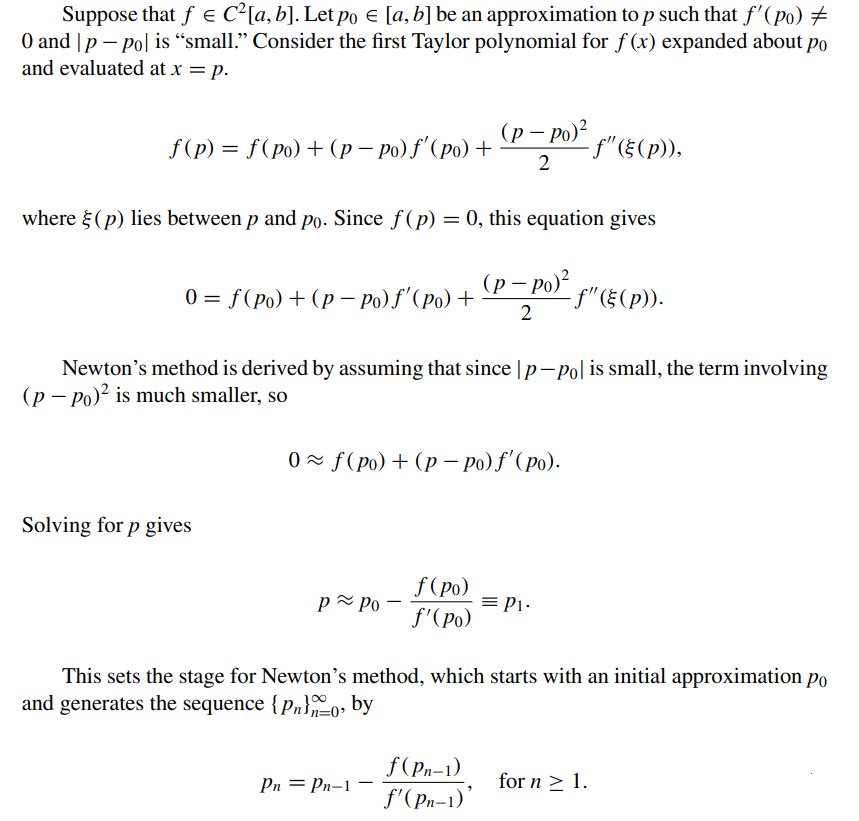 

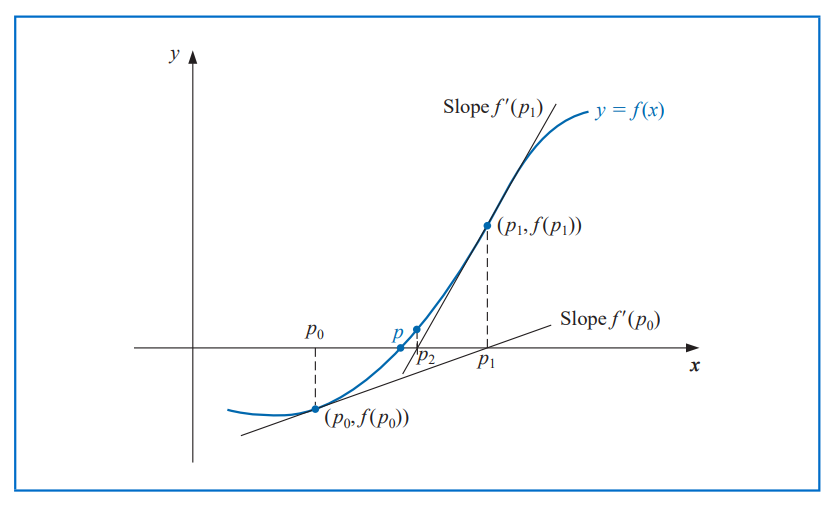

load data_newton_raphson.mat
newton_raphson(apx,n,tol)

2th Iteration result 2.843368e+00

3th Iteration result 2.781178e+00

4th Iteration result 2.756612e+00

5th Iteration result 2.746931e+00

6th Iteration result 2.743119e+00

7th Iteration result 2.741619e+00

8th Iteration result 2.741029e+00

9th Iteration result 2.740797e+00

10th Iteration result 2.740705e+00

11th Iteration result 2.740669e+00

12th Iteration result 2.740655e+00

13th Iteration result 2.740650e+00

14th Iteration result 2.740648e+00


Approximate solution,xn =  2.74064665 


function newton_raphson(apx,n,tol)
f = @(x) x*log10(x)-1.2;
fd = @(x) log10(x)/log10(10) + 1/log10(10);
p0 = apx;
%p0 = input('Enter initial approximation: ');
%n = input('Enter no. of iterations, n: ');
%tol = input('Enter tolerance, tol:  ');
i = 1;
while i <= n
    d = f(p0) / fd(p0);   
    p0 = p0 - d;          
    if abs(d) < tol       
        fprintf('\n\nApproximate solution,xn = %11.8f \n', p0);
        break;
    else
        i = i+1; 
        fprintf('\n%dth Iteration result %d\n',i, p0);
    end
end
end 
